实现 van der Pol 振荡方程

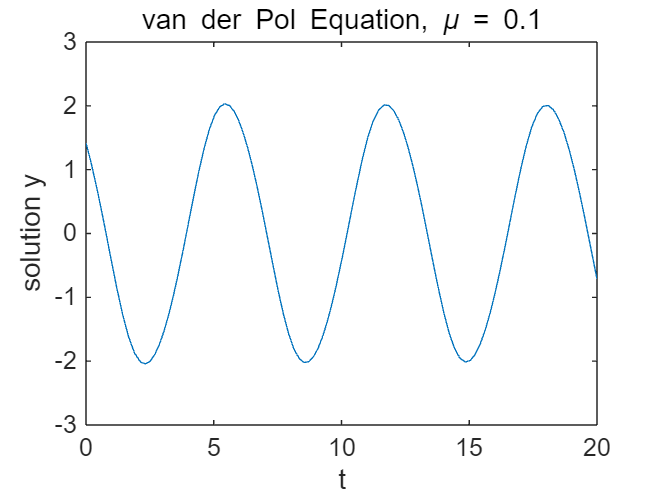

% 负值呈现阻尼振荡，正值为稳态振荡

tspan = [0 20];
y0 = [1.414; -1.414];
Mu = 0.1;
ode = @(t,y) vanderpoldemo(t,y,Mu);
[t,y] = ode45(ode, tspan, y0);

% Plot solution
plot(t,y(:,1))
xlabel('t')
ylabel('solution y')
title(['van der Pol Equation, \mu = ', num2str(Mu)])